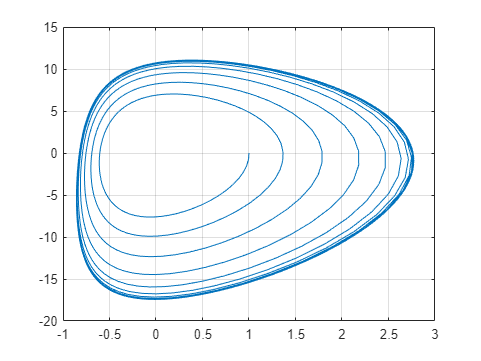

% Initial conditions (t=0)
h=0.01;
tf=30;
N=ceil(tf/h);

t=zeros(1,N+1);
x=zeros(1,N+1);
y=zeros(1,N+1);

t(1)=0;
x(1)=1;
y(1)=0;

[x,y] = RK4(t,x,y);

plot(x,y)
grid on
hold on

% t(1)=0;
% x(1)=3;
% y(1)=0;
% 
% [x,y] = RK4(t,x,y);
% 
% plot(x,y)
% grid on
hold off

%parallelisable

p=[];
for i=1:N-1
    if (y(i)*y(i+1))<=0
        p(end+1)=i;
    end
end

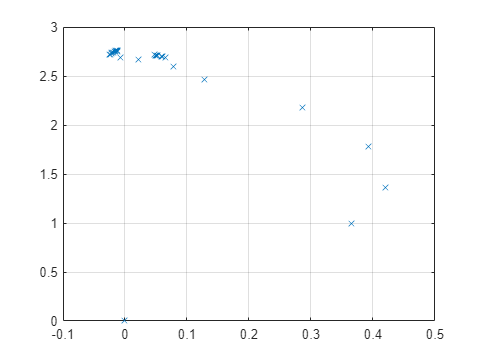

 %parallelisable

xdif=zeros(1,size(p,2)-1);
x2=zeros(1,size(p,2)-1);
M=size(p,2)-2;
iter = 1;

 for i=1:2:M
    x2(iter)=x(p(i+2))-x(p(i));
    xdif(iter)=x(p(i));
    iter=iter+1;
 end

 plot(x2,xdif,"x")
 grid on

function [x,y] = RK4(t,x,y)

% Example parameters
a=-10;
b=2.7;
c=0.4;
d=-437.5;
e=0.003;

% ODE
dxdt=@(t,x,y) x^2 + x*y + y;
dydt=@(t,x,y) a*x^2 + b*x*y + c*y^2 + d*x + e*y;

% Step size
h=0.01;
tf=30;
N=ceil(tf/h);

% Runge-Kutta 4

    for i=1:N
        t(i+1)=t(i)+h;
    
        k1x=dxdt(t(i), x(i), y(i));
        k1y=dydt(t(i), x(i), y(i));
    
        k2x=dxdt(t(i)+h/2, x(i)+h/2*k1x, y(i)+h/2*k1y);
        k2y=dxdt(t(i)+h/2, x(i)+h/2*k1x, y(i)+h/2*k1y);
    
        k3x=dxdt(t(i)+h/2, x(i)+h/2*k2x, y(i)+h/2*k2y);
        k3y=dxdt(t(i)+h/2, x(i)+h/2*k2x, y(i)+h/2*k2y);
    
        k4x=dxdt(t(i)+h, x(i)+h*k3x, y(i)+h*k3y);
        k4y=dxdt(t(i)+h, x(i)+h*k3x, y(i)+h*k3y);
    
        x(i+1)=x(i) + h/6*(k1x+2*k2x+2*k3x+k4x);
        y(i+1)=y(i) + h/6*(k1y+2*k2y+2*k3y+k4y);
    end
end